# Does Secondary Structure have a strong effect?

## Dimerization of coil SC

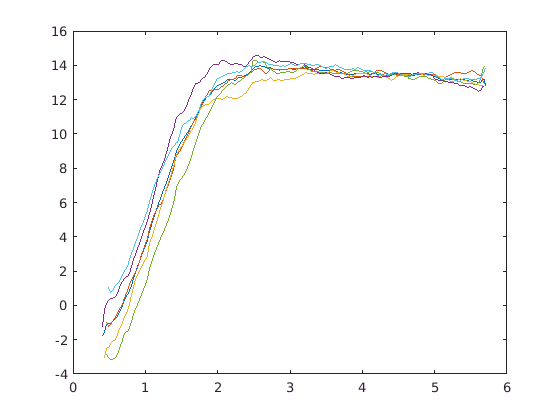

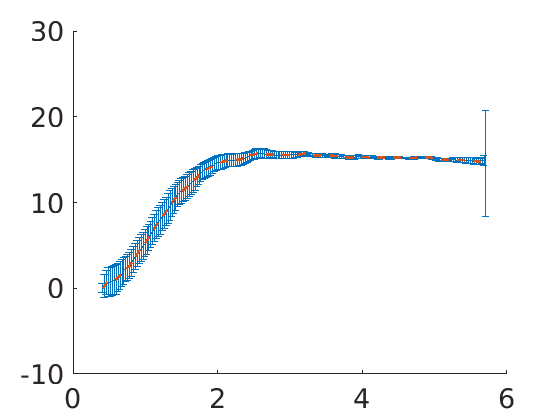

addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');
wdirb = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/martini-assembly/pmf2ndStructCheck/coil';
%minmaxxs = zeros(6,2);
tstart = 5000;
tinterval = 5000;
tend = 30000;
remove_entropic = 1;
wdir = [wdirb '/5_umbrella'];
[profcoil,errscoil] = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,[4 5 4 5 4 5 4 5 4 5]);

## Dimerization of helix SC

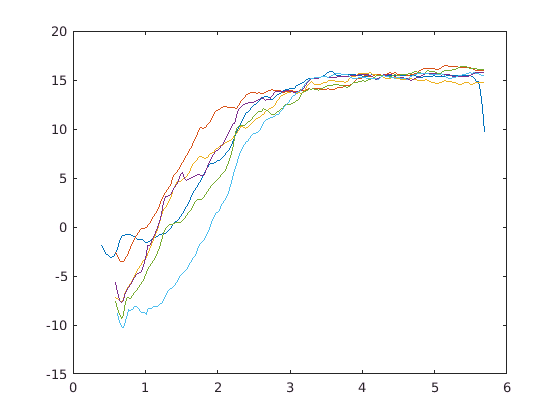

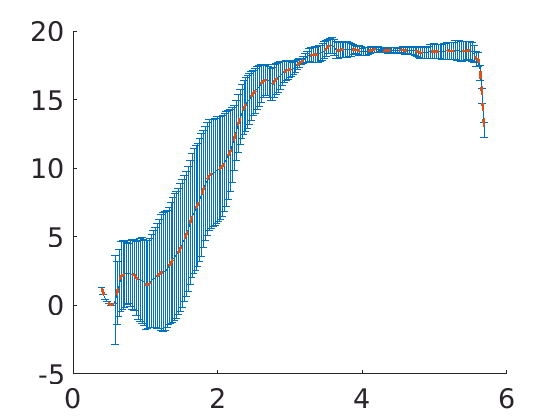

addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');
wdirb = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/martini-assembly/pmf2ndStructCheck/helix';
%minmaxxs = zeros(6,2);
tstart = 0;
tinterval = 2000;
tend = 10000;
remove_entropic = 1;
wdir = [wdirb '/5_umbrella'];
[profhelix,errshelix] = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,[4 5 4 5 4 5 4 5 4 5]);

## Dimerization of helix SC

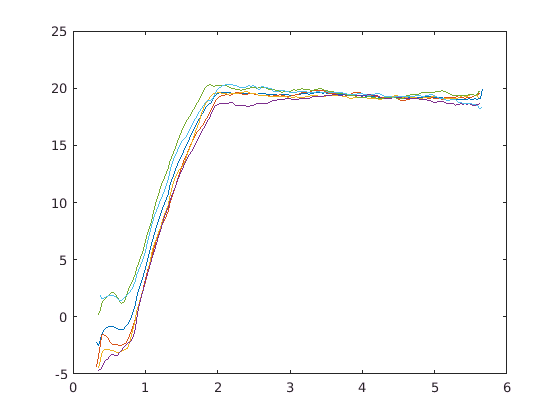

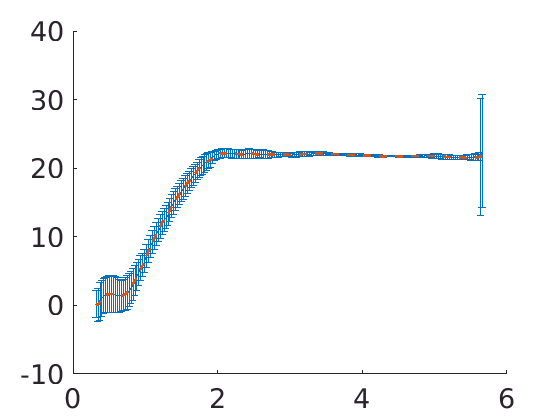

addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');
wdirb = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/martini-assembly/pmf2ndStructCheck/tother';
%minmaxxs = zeros(6,2);
tstart = 5000;
tinterval = 5000;
tend = 30000;
remove_entropic = 1;
wdir = [wdirb '/5_umbrella'];
[proftother,errstother] = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,[4 5 4 5 4 5 4 5 4 5]);

## Compare

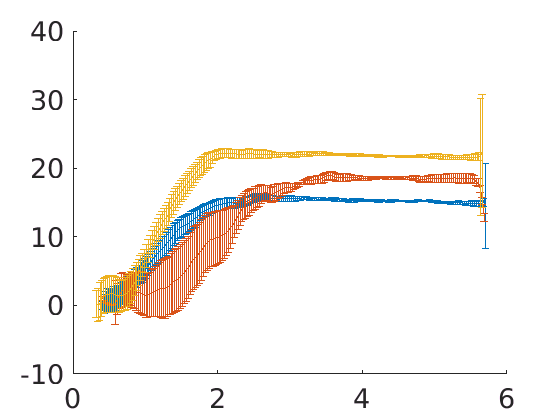

figure()
hold on
errorbar(profcoil(:,1),profcoil(:,2)-min(profcoil(:,2)),errscoil)
errorbar(profhelix(:,1),profhelix(:,2)-min(profhelix(:,2)),errshelix)
errorbar(proftother(:,1),proftother(:,2)-min(proftother(:,2)),errstother)
set(gca,'fontsize',20)

## Check DFMI and DGAG

This should eventually compare to atomistic.

**DGAG**

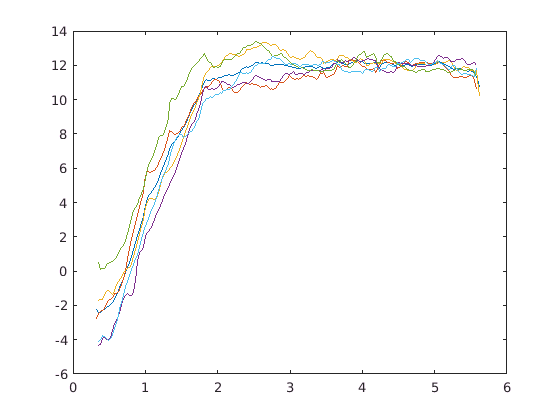

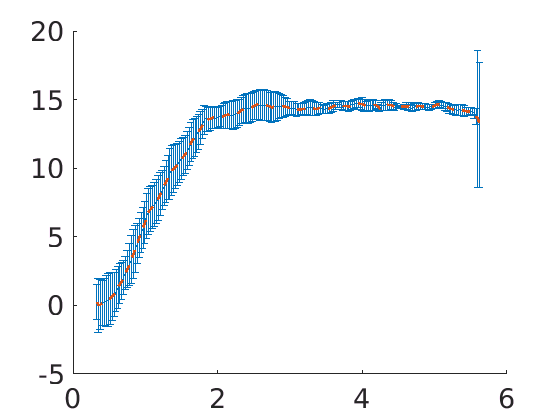

addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');
wdirb = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/martini-assembly/pmf2ndStructCheck/coildgag';
%minmaxxs = zeros(6,2);
tstart = 1000;
tinterval = 5000;
tend = 16000;
remove_entropic = 1;
wdir = [wdirb '/5_umbrella'];
[profcoildgag,errscoildgag] = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,[4 5 4 5 4 5 4 5 4 5]);

**DFMI**

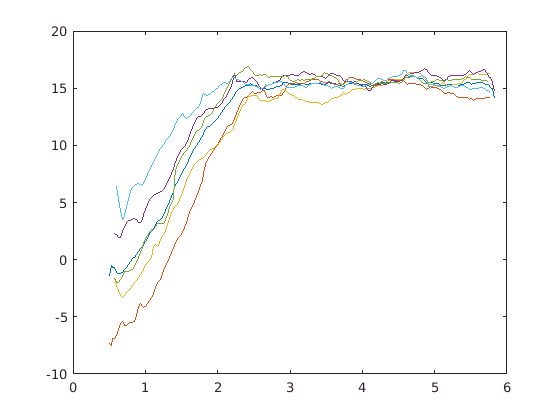

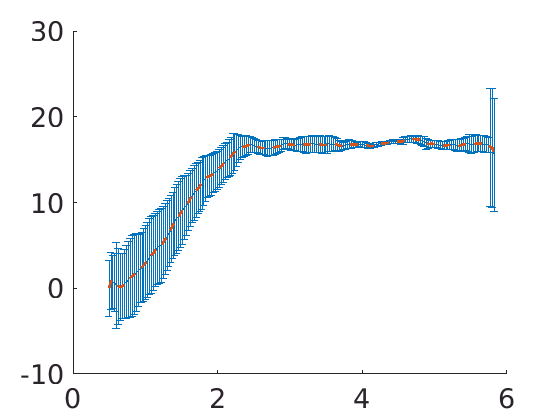

addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');
wdirb = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/martini-assembly/pmf2ndStructCheck/coildfmi';
%minmaxxs = zeros(6,2);
tstart = 1000;
tinterval = 5000;
tend = 16000;
remove_entropic = 1;
wdir = [wdirb '/5_umbrella'];
[profcoildfmi,errscoildfmi] = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,[4 5 4 5 4 5 4 5 4 5]);